Task2 Dynamic Dijkstra 

figure;
disp("Djikstra's")

Djikstra's


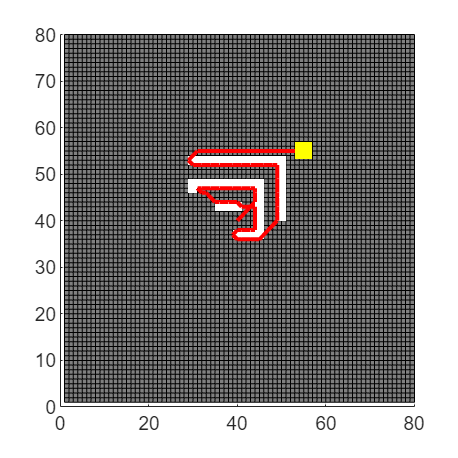

PushCounter: 161963


PopCounter: 78021


createMaze_1;

grid=zeros(size(Maze.map,1));
surf(grid')
fig=gcf;
fig.Position=[10 10 500 500];
colormap(gray)
view(2)
hold all

    map = Maze.map;
    ModifiedMaze = zeros(80);
    robotPosition = Maze.start;

    %  push and pop variabels 
    push = 0;
    pop = 0;

   while 1

  
    start = robotPosition;
    goal = Maze.goal;
    
    % costs 
    diagonalCost = sqrt(2);  
    straightCost = 1;        
    
    % Initialize  
    priorityQuene = containers.Map();  
    Cost_Values = inf(size(map));   
    Pointers = zeros(size(map, 1), size(map, 2), 2);  
    
    
    Cost_Values(start(1), start(2)) = 0;
    priorityQuene(num2str(start)) = Cost_Values(start(1), start(2));
    
    while ~isempty(priorityQuene)
        
        keys = priorityQuene.keys;
        [~, minIdx] = min(cell2mat(priorityQuene.values));
        currentStr = keys{minIdx};
        current = str2num(currentStr);
        priorityQuene.remove(currentStr);

        % popcounter
        pop = pop + 1;
        
        % when we reach the goal
        if isequal(current, goal)
            
            path = regeneratPath(Pointers, current);
            break
        end
        
        
        neighbors = getNeighbors(current, ModifiedMaze);
        
        for i = 1:size(neighbors, 1)
            neighbor = neighbors(i,:);
            
            % Calculate costs
            if abs(neighbor(1) - current(1)) + abs(neighbor(2) - current(2)) == 2
            
                cost = diagonalCost;
            else
                
                cost = straightCost;
            end
            
            % Calculate new Value
            new_Cost_Value = Cost_Values(current(1), current(2)) + cost;
            
            if new_Cost_Value <= Cost_Values(neighbor(1), neighbor(2))
               
                Cost_Values(neighbor(1), neighbor(2)) = new_Cost_Value;
                Pointers(neighbor(1), neighbor(2), :) = current;
                
                priorityQuene(num2str(neighbor)) = Cost_Values(neighbor(1), neighbor(2));
           
                % pushcounter
                push = push + 1;
            end
        end
  
    end

    done = true;

    for i = 1:size(path, 1)
        pos = path(i, :);
        if map(pos(1), pos(2)) == inf
            ModifiedMaze(pos(1), pos(2)) = inf;
            done = false;

            plot(pos(1), pos(2),'s','LineWidth',1,'MarkerFaceColor','w','color','w', 'MarkerSize',5);
            drawnow;
            break
        else
            oldPos = robotPosition;
            robotPosition = pos;

            x = [oldPos(1), robotPosition(1)];
            y = [oldPos(2), robotPosition(2)];
            plot(x, y, 'r', 'LineWidth', 2);
            plot(goal(1), goal(2), 's', 'LineWidth', 1, 'MarkerFaceColor', 'y', 'color', 'y', 'MarkerSize', 10)
            drawnow;
        end
    end

    if  done == true
        disp("PushCounter: " + push);
        disp("PopCounter: " + pop);
        break
    end
  % when we find no path
    path = [];
   end

Dynamic A*

figure;

createMaze_1;
disp('A*')

A*


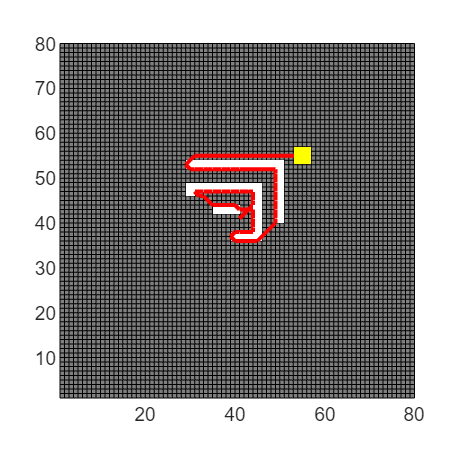

PushCounter: 16615


PopCounter: 6650


hold on

grid=zeros(size(Maze.map,1));
surf(grid')
fig=gcf;
fig.Position=[10 10 500 500];
colormap(gray)
view(2)
hold on

    map = Maze.map;
    ModifiedMaze = zeros(80);
    robotPosition = Maze.start;

    %  push and pop variabels 
    push = 0;
    pop = 0;

   while 1

   
    start = robotPosition;
    goal = Maze.goal;
    
    
    diagonalCost = sqrt(2);  
    straightCost = 1;        
    
    
    priorityqueue = containers.Map();  
    Cost_Values = inf(size(map));    
    Values = inf(size(map));    
    pointers = zeros(size(map, 1), size(map, 2), 2);  
    
    
    Cost_Values(start(1), start(2)) = 0;
    Values(start(1), start(2)) = heuristic(start, goal);
    priorityqueue(num2str(start)) = Values(start(1), start(2));
    

    while ~isempty(priorityqueue)
        
        keys = priorityqueue.keys;
        [~, minIdx] = min(cell2mat(priorityqueue.values));
        currentStr = keys{minIdx};
        current = str2num(currentStr);
        priorityqueue.remove(currentStr);
        
        % popcounter
        pop = pop + 1;

        if isequal(current, goal)
           
            path = regeneratPath(pointers, current);
            break
        end
        
        neighbors = getNeighbors(current, ModifiedMaze);
        
        for i = 1:size(neighbors, 1)
            neighbor = neighbors(i,:);
            
            
            if abs(neighbor(1) - current(1)) + abs(neighbor(2) - current(2)) == 2
                
                cost = diagonalCost;
            else
                
                cost = straightCost;
            end
            
            %
            newG = Cost_Values(current(1), current(2)) + cost;
            
            if newG <= Cost_Values(neighbor(1), neighbor(2))
                
                Cost_Values(neighbor(1), neighbor(2)) = newG;
                Values(neighbor(1), neighbor(2)) = newG + heuristic(neighbor, goal);
                pointers(neighbor(1), neighbor(2), :) = current;
                
                priorityqueue(num2str(neighbor)) = Values(neighbor(1), neighbor(2));
            
                % pushcounter
                push = push + 1;
            end
        end
    
    end

    done = true;

    for i = 1:size(path, 1)
        pos = path(i, :);
        if map(pos(1), pos(2)) == inf
            ModifiedMaze(pos(1), pos(2)) = inf;
            done = false;

            plot(pos(1), pos(2),'s','LineWidth',1,'MarkerFaceColor','w','color','w', 'MarkerSize',5);
            drawnow;
                        break
        else
            oldPos = robotPosition;
            robotPosition = pos;

            x = [oldPos(1), robotPosition(1)];
            y = [oldPos(2), robotPosition(2)];
            plot(x, y, 'r', 'LineWidth', 2);
            plot(goal(1), goal(2), 's', 'LineWidth', 1, 'MarkerFaceColor', 'y', 'color', 'y', 'MarkerSize', 10)
            drawnow;
        end
    end

    if  done == true
        disp("PushCounter: " + push);
        disp("PopCounter: " + pop);
        break
    end
    path = [];
   end

Function Heuristic

function h = heuristic(position, goal)
    % Euclidean distance 
    h = sqrt((position(1) - goal(1))^2 + (position(2) - goal(2))^2);
end

Neighbor function

function neighbors = getNeighbors(position, map)
      
    % Extract x and y coordinates of the current point
    x = position(1);
    y = position(2);

   
    dx = [-1, -1, 0, 0, 1, 1, -1, 1]; % Displacement in x-direction for each neighbor
    dy = [-1, 0, 1, -1, 0, 1, 1, -1]; % Displacement in y-direction for each neighbor
    
  
    nx = x + dx; % Potential x-coordinates of neighbors
    ny = y + dy; % Potential y-coordinates of neighbors

   % Identify indices of neighbors within map boundaries and not obstacles
    valid_indices = nx >= 1 & nx <= size(map, 1) & ny >= 1 & ny <= size(map, 2) & map(nx + (ny - 1) * size(map, 1)) ~= inf;
    
    neighbors = [nx(valid_indices)', ny(valid_indices)']; % Store valid neighbor coordinates in a matrix
end

Regenerate Path

function path = regeneratPath(parentPointers, goal)
    % Reconstruct the path from the goal to the start using pointers
    path = [];
    current = goal;
    
    while ~isequal(current, [0, 0])
        path = [current; path];
        current = squeeze(parentPointers(current(1), current(2), :))';
    end
 
end